# Matched Filters

## ADSI Problem 6.1: Matched filters

Consider a deterministic signal that is only non-zero in the vicinity of *n*=0 as shown below and zero for all other values of $n$.

        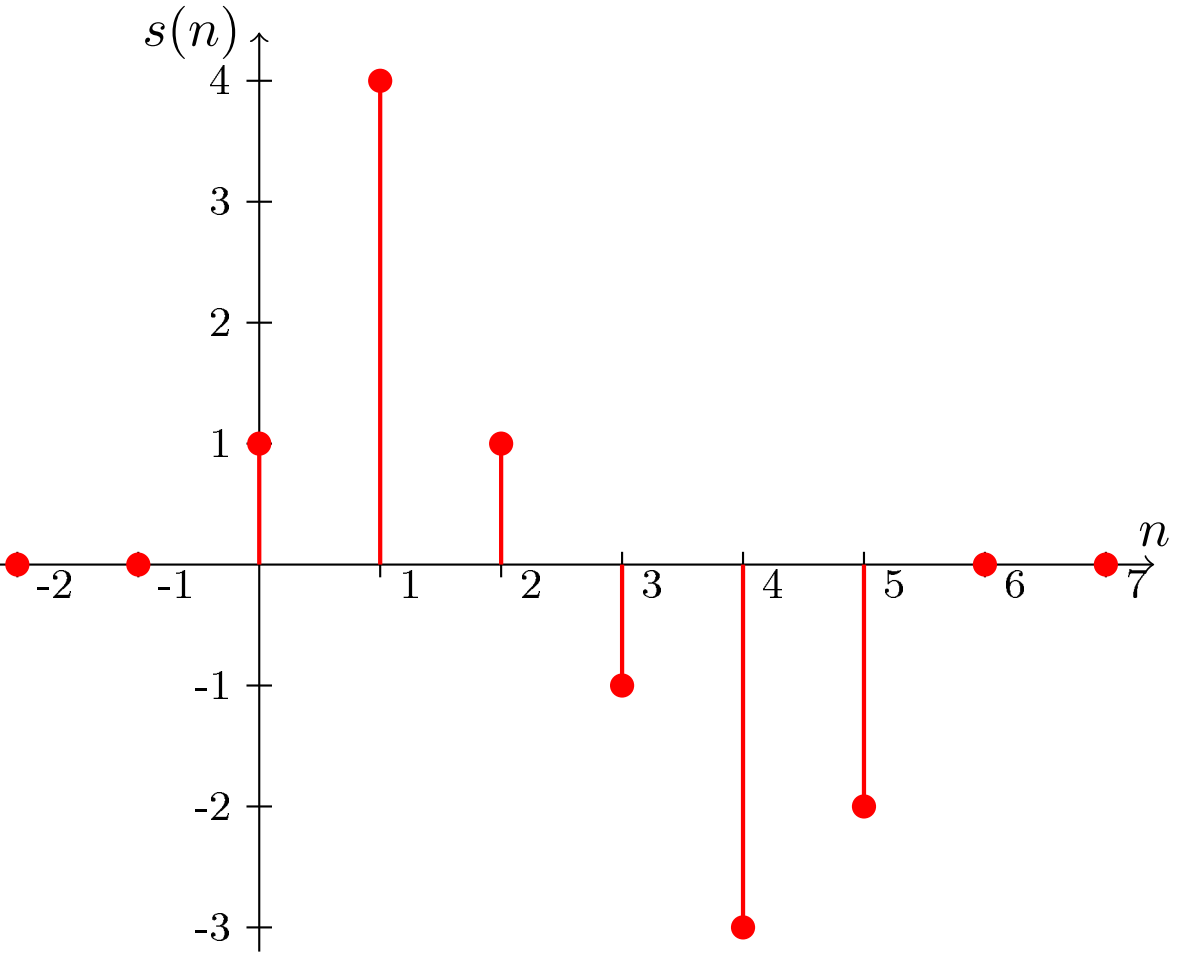

The signal is disturbed by additive noise from an AR(3) process given by

        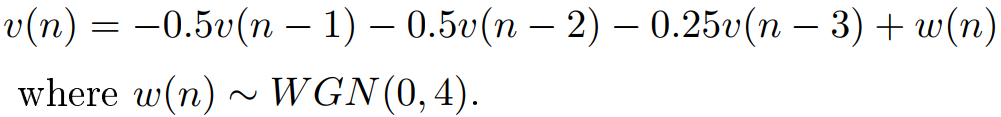

The goal of this problem is to construct a matched filter that can help us distinguish between the presence or absence of the signal in the noise.  

clear variables;

### 1) Plot a realisation of the signal with the added noise

*Create a realization of the noise and add the signal somewhere in the noise. Plot the result and comment on whether the signal is detectable.  *

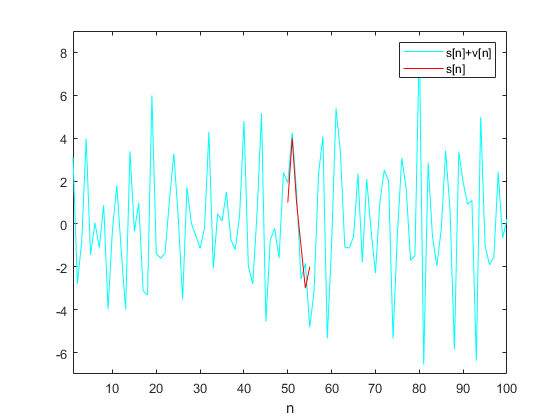

D = 50; % The place to embed signal into the noise

% Generate the deterministic signal s[n]
s = [1, 4, 1, -1, -3, -2]';

% Generate white noise w[n] with zero mean and variance 4
w_var = 4;
w = sqrt(w_var) * randn(10000, 1);

% Generate noise from an AR(3) process
b = 1;
a = [1, 0.5, 0.5, 0.25];
v = filter(b, a, w);

% Extract 100 samples to remove the transient effect 
% at the beginning and at the end of the filtered signal
x = v(500:600);

% Embed the signal s[n] in v[n] from D
s_in_x_start = D;
s_in_x_end =   D + length(s) - 1;
x(s_in_x_start:s_in_x_end) = x(s_in_x_start:s_in_x_end) + s; 

plot(1:length(x),       x, 'c', ...
     s_in_x_start:s_in_x_end, s, 'r') % the signal is completely invisible
legend('s[n]+v[n]', 's[n]')
xlabel('n')
xlim([1,100])
ylim([-7, 9])

The signal is cannot be distinguished from the noise.

### [✔] 2) Plot the power density spectrum of the noise and spectrum of the signal

*Plot the power density spectrum of the noise and spectrum of the signal, see Eq. (14.91).  *

The noise is generated by an AR(3) process plus some white Gaussian noise:

        

We can determine the Power Density Spectrum of an ARMA(p,q) process is given by

        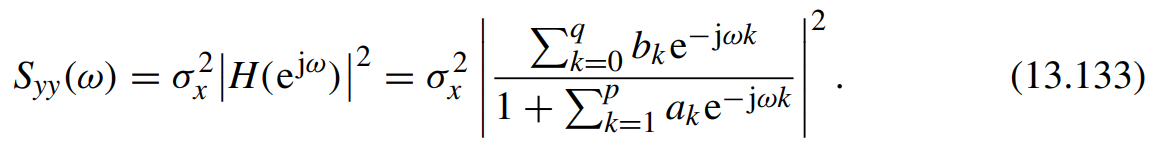

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


For this problem, we have:

        
$$S_{\mathrm{vv}} \left(\omega \right)=4{\left|\frac{1}{1+0\ldotp 5e^{-j\omega } +0\ldotp 5e^{-\mathrm{j2}\omega } +0\ldotp 25e^{-\mathrm{j3}\omega } }\right|}^2$$


The algorithm is as follows:

- Use the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model, 

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The algorithm is implemented in the functions `ar2psd()` function:

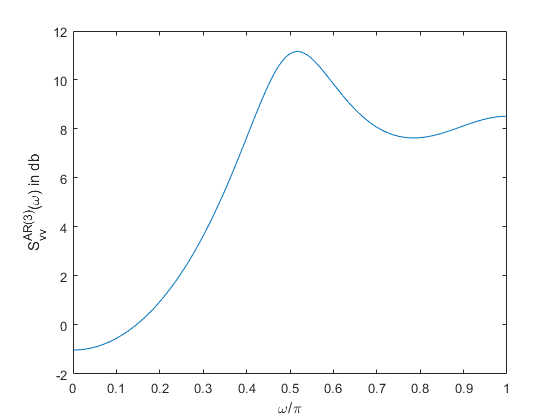

N = 256;

a = [0.5, 0.5, 0.25]; % The coefficients of the AR(3) model
w_var = 4; % The variance of white noise
[S_vv, w] = ar2psd(a, w_var, N); % Compute the PSD of AR(3) model

plot(w/pi, pow2db(S_vv))
xlabel('\omega/\pi')
ylabel('S_{vv}^{AR(3)}(\omega) in db')

We can plot the spectrum of the signal $s\left(n\right)$ using the `freqz()` function:

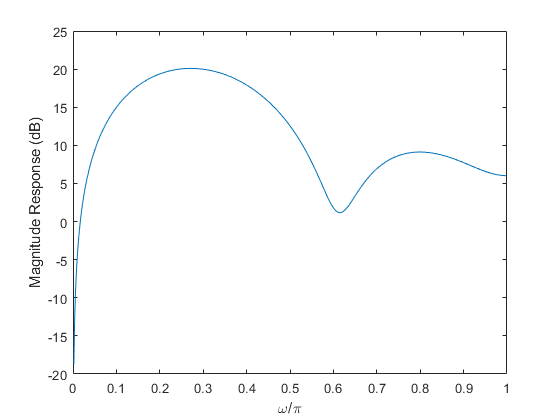

[H,w2] = freqz(s, 1);
plot(w2/pi, 20*log10(abs(H)))
xlabel('\omega/\pi')
ylabel('Magnitude Response (dB)')

### [✔] 3) Calculate the matched filter

*Calculate the matched filter, the frequency response of the matched filter and the optimum signal to noise ratio. You can use *`xcorr`* on the noise realization to find *${\mathit{\mathbf{R}}}_v$*.  *

The impulse response of the matched filter is given by:

        

where $k$ is the normalisation factor. Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        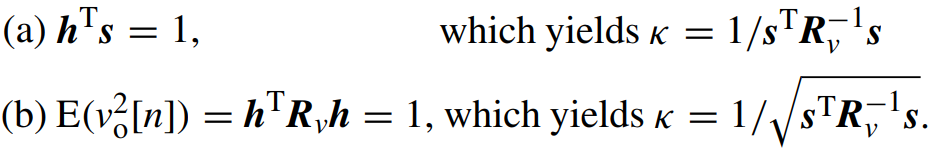

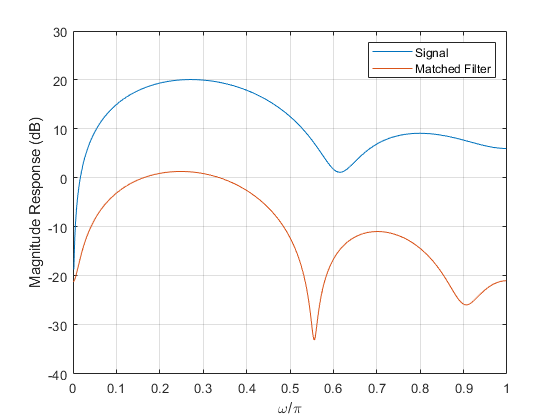

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
[r_vv, ~] = xcorr(v, p-1, 'biased');
R_vv = toeplitz(r_vv(p:end));

% Compute normalisation factor
k = 1/sqrt(s'*(R_vv\s)); % Same as 1/sqrt(s'*inv(R_vv)*s)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

[H_s, w_s] = freqz(s, 1);
[H_h, w_h] = freqz(h, 1);
plot(w_s/pi, 20*log10(abs(H_s)), w_h/pi, 20*log10(abs(H_h)))
legend('Signal', 'Matched Filter')
xlabel('\omega/\pi')
ylabel('Magnitude Response (dB)')
grid on;

The maximum possible value of the output SNR is given by:

        

Since the attenuation factor $a$ is not given in this problem, we assume that it is 1:

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 11.0394

### [?] 4) Does the frequency response of the matched filter make sense?

*Does the frequency response of the matched filter make sense seen in relation with the spectra from question 2?  *

In question 2) we found that the AR(3) noise model has peak power at 0.5.

        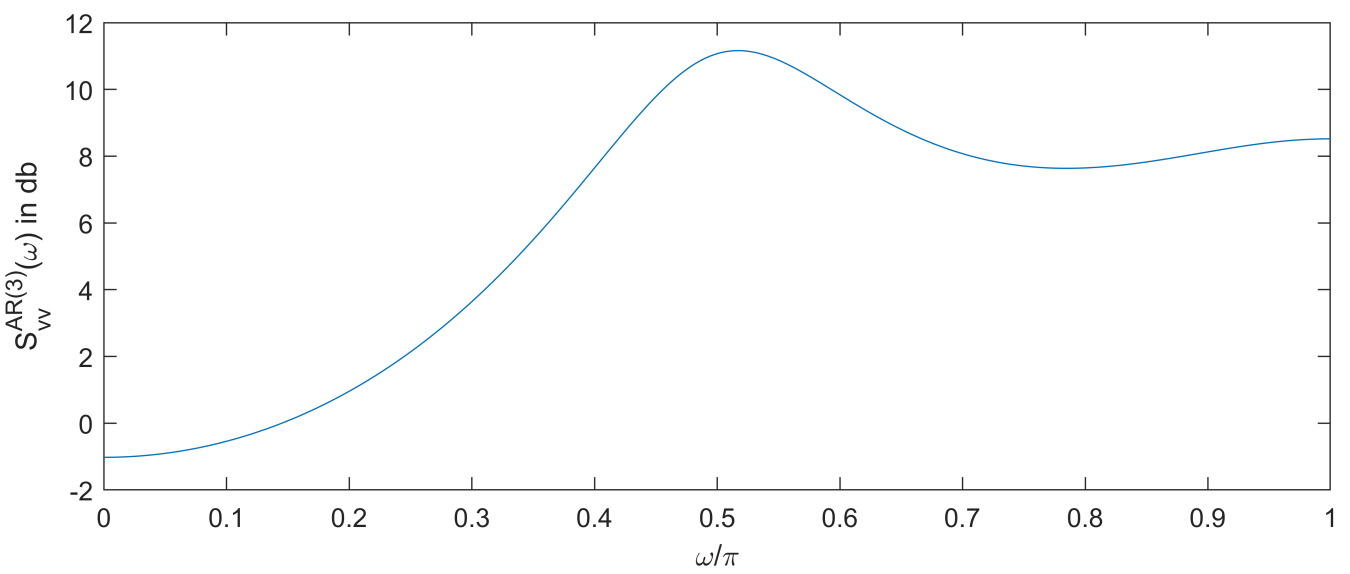

Looking at the frequency response of the signal, we observe that it peaks around 0.25 and dips around 20 dB at around 0.6. 

The frequency response of the matched filter shows that it is minimising the noise in the region at around 0.55. The noise power peaks at around 0.5

        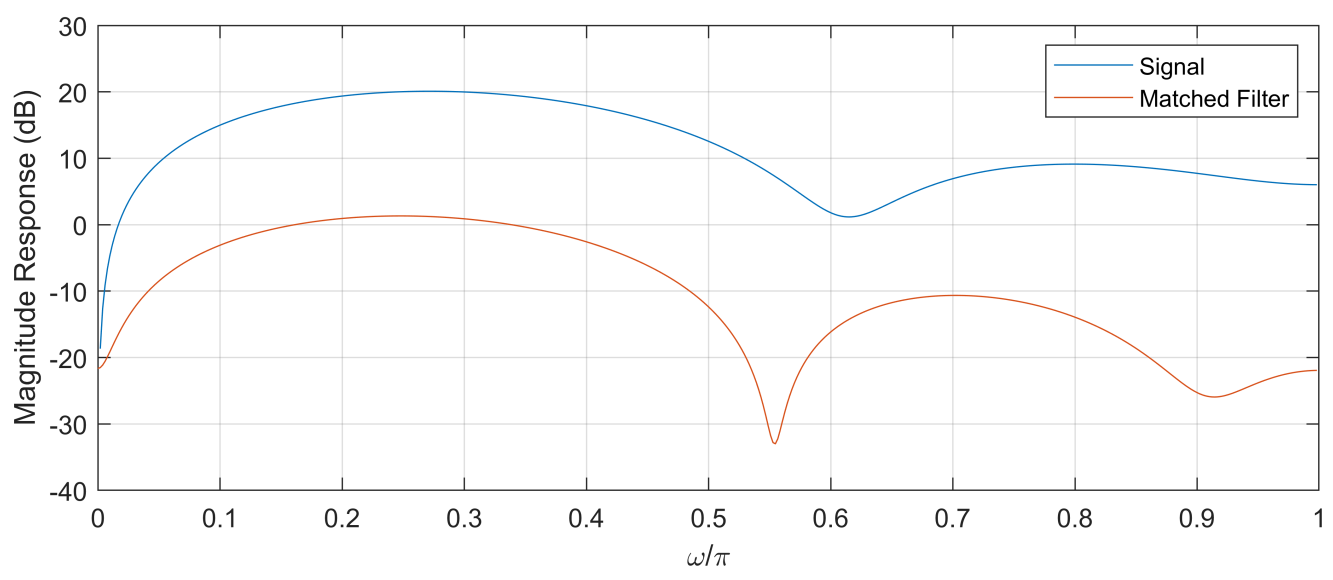

### [✔] 5) How efficient is the matched filter?

*Plot the signal before and after the matched filter as well as the square of the output of the matched filter on the same graph and comment on the effiency of the matched filter in our quest to detect the presence of the signal.  *

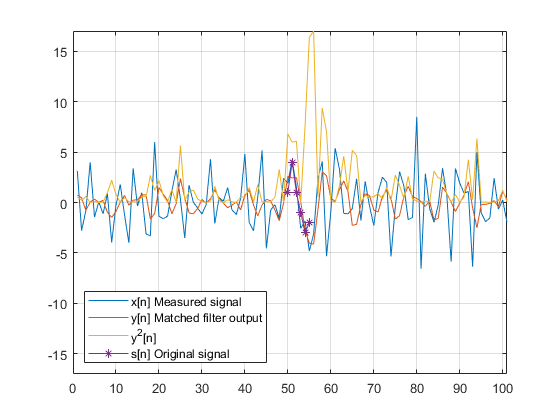

% x(n) is the 100 samples extracted from the noise signal v(n)
% y(n) is the result of feeding x(n) to the matched filter
y = filter(h, 1, x);
y_squared = y.^2;

n = 1:length(x);

n2 = s_in_x_start:s_in_x_end;
xs = s;

plot(n,x, n,y, n,y_squared,  n2,xs,'*-')
xlim([0, numel(n)])
ylim([-max(y_squared), max(y_squared)])
legend({'x[n] Measured signal', 'y[n] Matched filter output', 'y^2[n]', 's[n] Original signal'}, ...
    'Location','southwest')

grid on;

It's close to impossible to find the orignal signal $s\left\lbrack n\right\rbrack$ in the measured signal $x\left\lbrack n\right\rbrack$. It is also difficult to detect $s\left\lbrack n\right\rbrack$ after filtering $x\left\lbrack n\right\rbrack$ with the matched filter i.e.,$y\left\lbrack n\right\rbrack$. It is easier to detect the original signal in the square of the output of the matched filter $y^2 \left\lbrack n\right\rbrack$. Running the code multiple times i.e., creating different realisations of the noise, we may see many false positives. The figure below shows an example of this. The highest response is measured at $n=6$ but we know that the signal is embedded in $n=50$.

        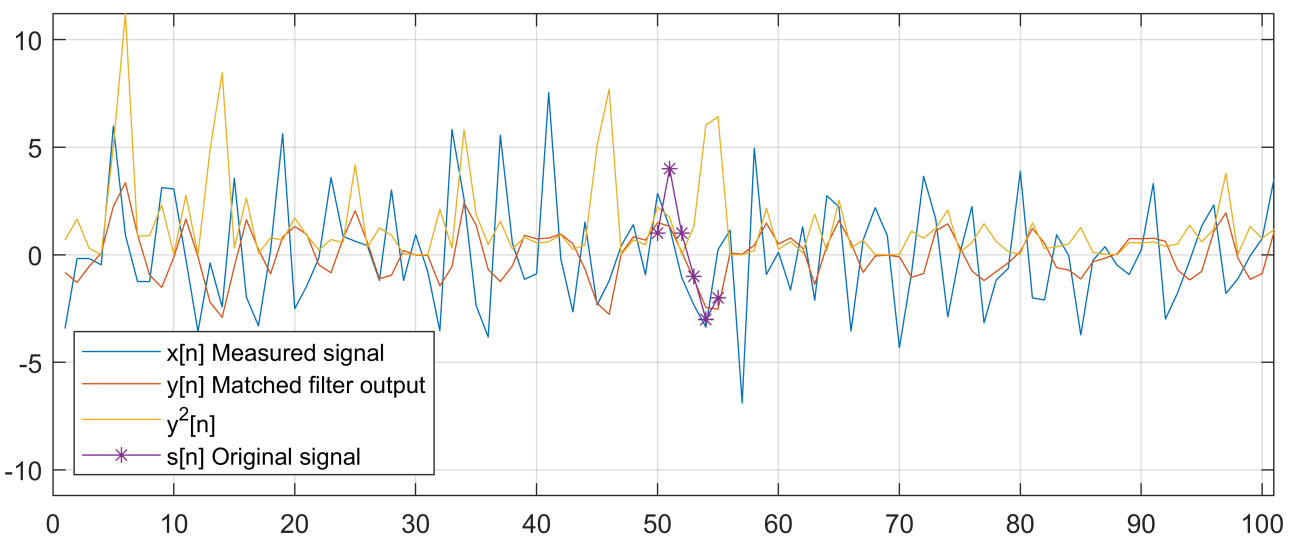

### [✔] 6) What happens to the optimum SNR when the noise is twice as powerful?

*Is the optimum signal to noise ratio halved if the AR(3) is instead driven by twice as powerful white noise, i.e. w(n) ∼ WGN(0,8)? Why or why not?*  

We will compute the SNR again but this time with $\sigma_w^2 =8$:

        

% Generate white noise w[n] with zero mean and variance 8
w2_var = 8;
w2 = sqrt(w2_var) * randn(10000, 1);

% Put the white noise through an AR(3) process
b = 1;
a = [1, 0.5, 0.5, 0.25];
v2 = filter(b, a, w2);

% Extract 100 samples to remove the transient effect 
% at the beginning and at the end of the filtered signal
x2 = v2(500:600);

p = numel(s); % Signal length

% The autocorrelation matrix must be MxM since
% its inverse is multiplied by a M-tap signal s(n)
[r_vv2, lags] = xcorr(x2, p-1, 'biased');
R_vv2 = toeplitz(r_vv2(p:end));

a = 1;
SNR2 = a^2 * s' * (R_vv2\s)

SNR2 = 7.3950

SNR2/SNR

ans = 0.6699

The optimal signal-to-noise-ratio is almost halved when the white noise is doubled. The reduction of SNR is not always decreased by a factor of though. Although the noise power is doubled, the shape of the optimum filter will change because it depends on the measured signal:

        

### [✔] 7) Compute SNR using a 6-tap moving average filter

*Assume that instead of the matched filter a simple 6-tap moving average filter is used instead. That is*

        
$$\mathit{\mathbf{h}}={\left\lbrack \begin{array}{cccccc}
\frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6}
\end{array}\right\rbrack }^T$$


*Calculate the signal to noise ratio when the moving average filter is used.*

We can compute the SNR using the following formula:

        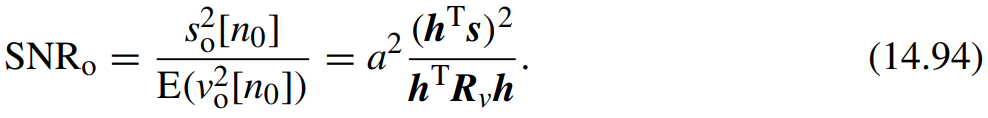

% h_avg = [1, 0, 1, 1, 1, 1]'./5;
h_avg = [1, 1, 1, 1, 1, 1]'./6;
a = 1;
SNR_avg = a^2 * (h_avg'*s)^2 / (h_avg'*R_vv*h_avg)

SNR_avg = 0

The SNR of the moving average filter is zero (or a number very close to zero). The moving average filter gives us the average of a signal. Since the original signal has zero mean, the average is zero. This is not surprising. If we change the filter, then the SNR is no longer zero.

h4 = [1, 0, 1, 1, 1, 1]'./5;
a = 1;
SNR4 = a^2 * (h4'*s)^2 / (h4'*R_vv*h4)

SNR4 = 1.4292

## Problems True/False

### Matched fiters are only applicable when the noise is white

The derivation of the matched filter makes no assumption of whether the noise is white or coloured. It should be noted though, that the interpretation of the filter is easier when the noise is white.

## Exam 2017 Problem 3: Detect presence of signal using matched filter

Consider the deterministic signal, *s*(*n*) shown below in blue. The signal is zero for all other values of  *n*.  

        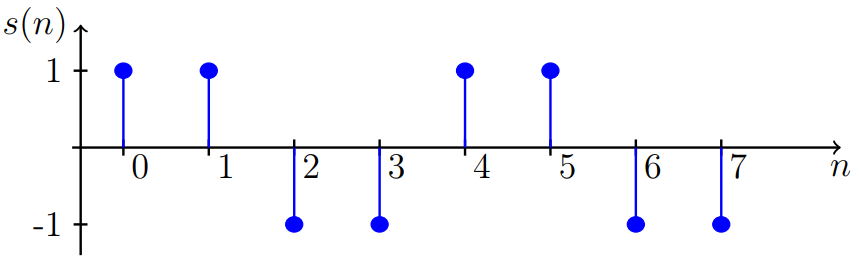

The signal is distorted by additive low frequency noise with autocorrelation $r_v \left(\ell \right)=0\ldotp 4^{|\ell |}$.

clear variables;

### 1) Design a matched filter and determine the improvement in SNR  

*Design a matched filter for detecting the presence of the signal and determine the improvement in signal to noise ratio. *

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        

s = [1, 1, -1, -1, 1, 1, -1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.4.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/(s'*(R_vv\s));       % Using (a)
% k = 1/sqrt(s'*(R_vv\s)); % Using (b)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

% Print the matched filter coefficients
h

h =     0.0735
    0.1422
   -0.1422
   -0.1422
    0.1422
    0.1422
   -0.1422
   -0.0735


The SNR at the input is given by:

        
$${\textrm{SNR}}_i =\frac{\mathrm{power}\;\mathrm{of}\;\mathrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}$$


SNR_i = s(1)^2/r_vv(1)

SNR_i = 1

The optimum SNR at the output is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 9.7143

The improvement in SNR is 9.7 (almost 10 times)

### 2) Discuss the improvement of SNR if a high-frequency signal is used

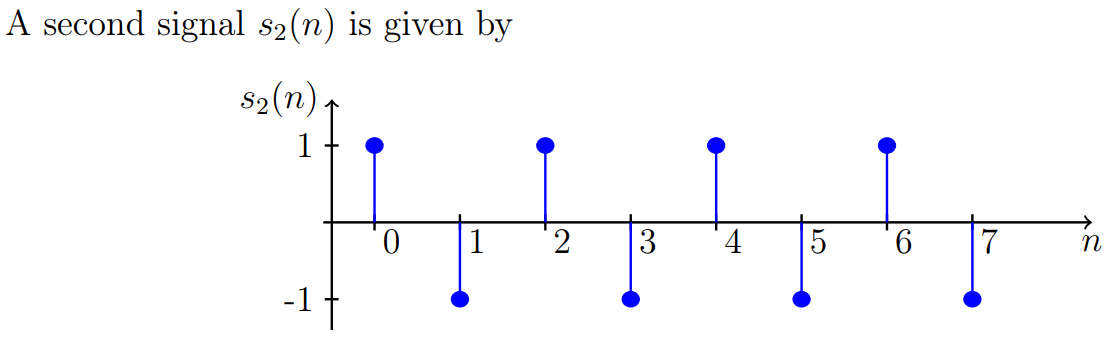

If we use $s_2 \left(n\right)$ instead of $s\left(n\right)$, the output SNR becomes 17.3:

s = [1, -1, 1, -1, 1, -1, 1, -1]';
p = numel(s); % Signal length
ell = 0:p-1;
r_vv = 0.4.^ell;
R_vv = toeplitz(r_vv);
a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 17.3333

The $s_2 \left(n\right)$ is similar to $s\left(n\right)$ but it oscillates faster i.e., has higher frequency than the $s\left(n\right)$ signal. Since the noise is at low frequency, it is easier to separate the $s_2 \left(n\right)$ signal from the noise. This means that a higher SNR can be expected from a signal with a higher frequency.

That is why the output SNR for $s_2 \left(n\right)$ is better than that for $s\left(n\right)$.

## Exam 2018 Problem 3: Improve SNR with a matched filter

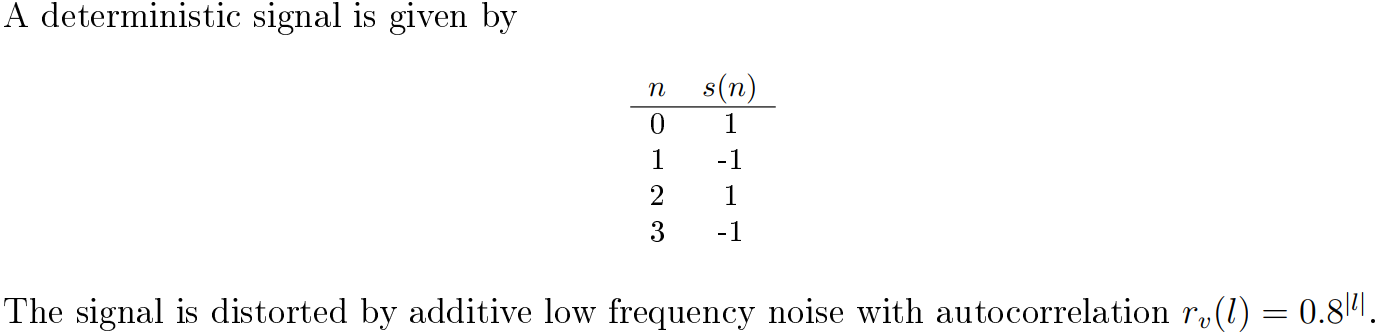

clear variables;

### 1) Design a matched filter to improve the SNR

*Design a matched filter to improve the signal to noise ratio and comment on the improvement.  *

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        

s = [1, -1, 1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/sqrt(s'*(R_vv\s));

% Compute the filter
h = k*(R_vv\s);

% Print the matched filter coefficients
h

h =     0.9449
   -1.7008
    1.7008
   -0.9449


The SNR at the input is given by:

        
$${\textrm{SNR}}_i =\frac{\mathrm{power}\;\mathrm{of}\;\mathrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}$$


SNR_i = s(1)^2/r_vv(1)

SNR_i = 1

The optimum SNR is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 28.0000

The improvement in SNR is 28 times.

### 2) Can SNR be improved by using a longer signal?

Yes, the SNR can be improved. With three blocks, the SNR is increased to 46:

s = [1, -1, 1, -1, 1, -1]';
p = numel(s);
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);
k = 1/sqrt(s'*(R_vv\s));
h = k*(R_vv\s);

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 46.0000

## Functions

function [S, w] = ar2psd(a, v, N)
% AR2PSD Compute the Power Spectral Density from AR(p) coefficients
%   [S, w] = ar2psd(a, v, N)
% a: AR(p) coefficients
% v: the variance
% N: number of points in the range [1, pi]
% S: the estimated power spectrum
% w: frequencies
    w = linspace(0, 1, N) * pi;
    
    % Compute the transfer function
    % Used Eq. (13.133) in the book
    H = ones(N, 1);
    for k=1:numel(a)
        H = H + a(k)*exp(-1j * w' * k);
    end
    H = 1./H;
    
    % Finally compute the PSD
    S = v * H.*conj(H);
end

function [h, SNR] = matched_filter(s, v, a)
% MATCHED_FILTER: Compute the impulse response of a matched filter and 
%                 and the corresponding output SNR.
%   [h, SNR] = matched_filter(s, v, a)
% s:   the signal
% v:   a realisation of the additive noise
% a:   the attenuation factor (default=1)
% h:   the impulse response of the matched filter
% SNR: the output SNR
    if nargin < 3
        a = 1;
    end

    p = numel(s); % Signal length
    
    % The autocorrelation matrix must be p x p since
    % its inverse is multiplied by a p-tap signal s(n)
    [r_vv, ~] = xcorr(v, p-1, 'biased');
    R_vv = toeplitz(r_vv(p:end));
    
    % The expression `R_vv^{-1} * s` is used multiple times,
    % so compute it once and reuse
    R_vv_inv_s = R_vv\s;
    
    % Compute normalisation factor
    k = 1/sqrt(s'*R_vv_inv_s);
    
    % Compute the filter
    h = k*R_vv_inv_s;
    
    % Compute the output SNR
    SNR = a^2 * s' * R_vv_inv_s;
end

function [x, v, s] = gen_noisy_signal(s_original, N, noise_var, D)
% Embeds a signal into a realisation of a WGN process
%  s_original: the original signal that needs to be embedded
%  N:          the number of samples of the noisy signal
%  noise_var:  the variance of WGN (default=1)
%  D:          the position of embedding
    if nargin < 4
        D = 0;
    end
    if nargin < 3
        noise_var = 1;
    end
    
    n = (1:N)';
    p = numel(s_original); % Signal length
    
    % Generate the signal.
    % Ensure that s[n] is zero when n is outside the interval [1, p]
    s = zeros(N, 1);
    s(n >= D+1 & n <= p+D) = s_original;
    
    % Generate the zero-mean WGN
    v = sqrt(noise_var) * randn(N, 1);
    
    % Generate the measured signal x[n]
    x = v + s;
end

function [S_xx, w] = psd_from_acrs(r_xx)
% Computes the power spectrum density based on the autocorrelation sequence
% This uses the Equation (13.119)
    w = (0:0.001:pi)';
    S_xx = r_xx(1) * ones(numel(w), 1);
    for l=2:length(r_xx)-1
        S_xx = S_xx + 2*r_xx(l+1) * cos(w*l);
    end
end